This script runs the entire analysis for the Kuparuk River Basin.

Some notes:

- detecting recession events is reasonably fast but fitting events is slow

- computing uncertainties is very slow (bootstrap fit)

- therefore, an option is included to either run each step or load pre-computed data

- in typical use, one might run this script once to generate the 'Events' data and save that

- then experiment with the 'fitevents' function and save the 'Fits' data

- then experiment with the 'globalfit' function and save the 'GlobalFit' data

NOTE: this script assumes it is being run in the folder that contains the data/ folder 

clearvars
close all
clc

Set the main options

savedata    = false;
sitename    = bfra.basinname('KUPARUK R NR DEADHORSE AK');
t1          = datetime(1990,1,1);   % start at 1990 for CALM
t2          = datetime(2020,12,31);
fitevents   = true;                % if true, run fitevents, otherwise load saved Fits
fitglobal   = true;                 % if true, run globalfit, otherwise load saved GlobalFit
plotfigs    = true;                 % if true, globalfit will produce figures
bootfit     = true;                % if true, uncertainties are computed by bootstrap resampling (very slow)
nreps       = 2;                    % number of bootstrap samples
fname       = 'data/Events.mat';    % this is the filename used to save all data including Events, Fits, and GlobalFit

Set the basin geomorphological parameters

A           = 8.6545e9;       % basin area
Dd          = 0.8;            % drainage density
D           = 0.47;           % reference aquifer thickness (mean alt from CALM)
L           = A*Dd/1000;      % active stream length

Load the streamflow data and the CALM-network active layer thickness data

load('data/dailyflow.mat','T','Q','R');
load('data/annualdata.mat','Data');

Set the algorithm options. Here we use a combination of default options and site-specific options.

opts.Events = bfra.setopts('events');
opts.Fits   = bfra.setopts('fits','drainagearea',A);

Get all recession events and then fit them

if fitevents == true
   [Events] = bfra.getevents(T,Q,R,opts.Events); 
   [K,Fits] = bfra.fitevents(Events,opts.Fits);
   
   if savedata == true
      save(fname,'Events','Fits','K','opts');
   end
   
else % load pre-saved data
   load(fname,'Events','Fits','K','opts');
end

Run the global fitting analysis. Uncertainties will only be computed if bootfit == true (very slow).

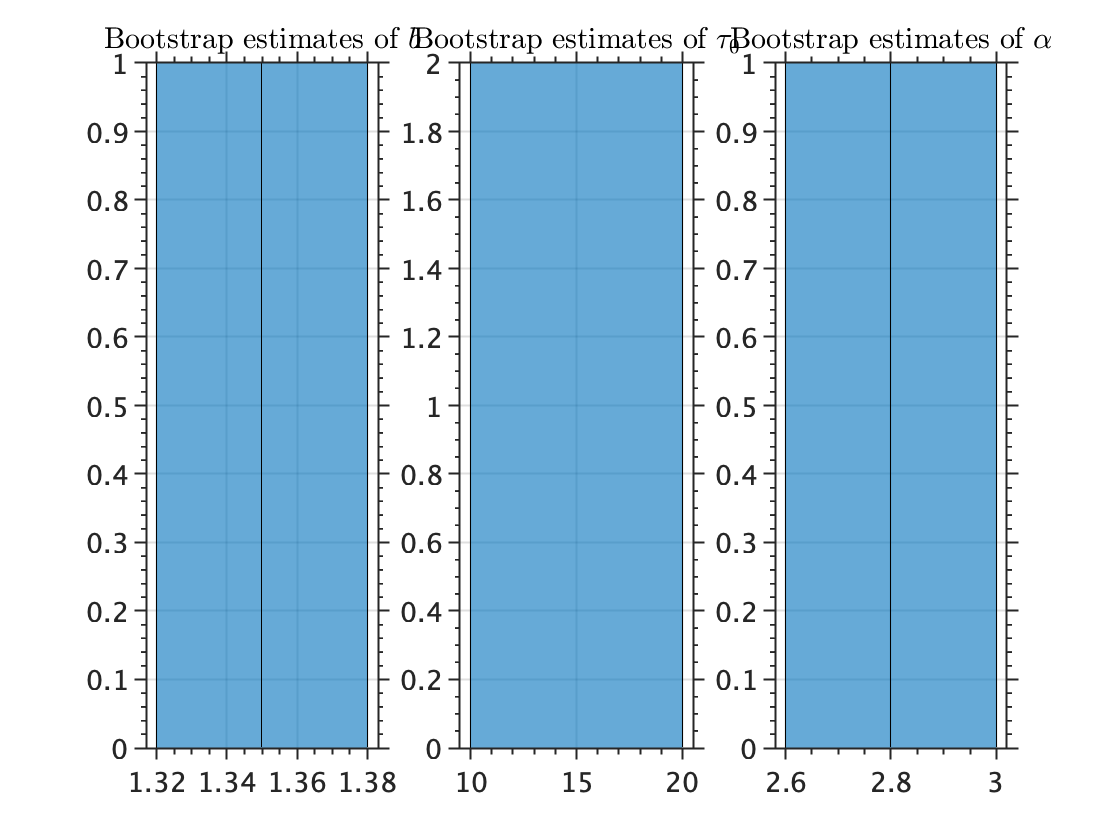

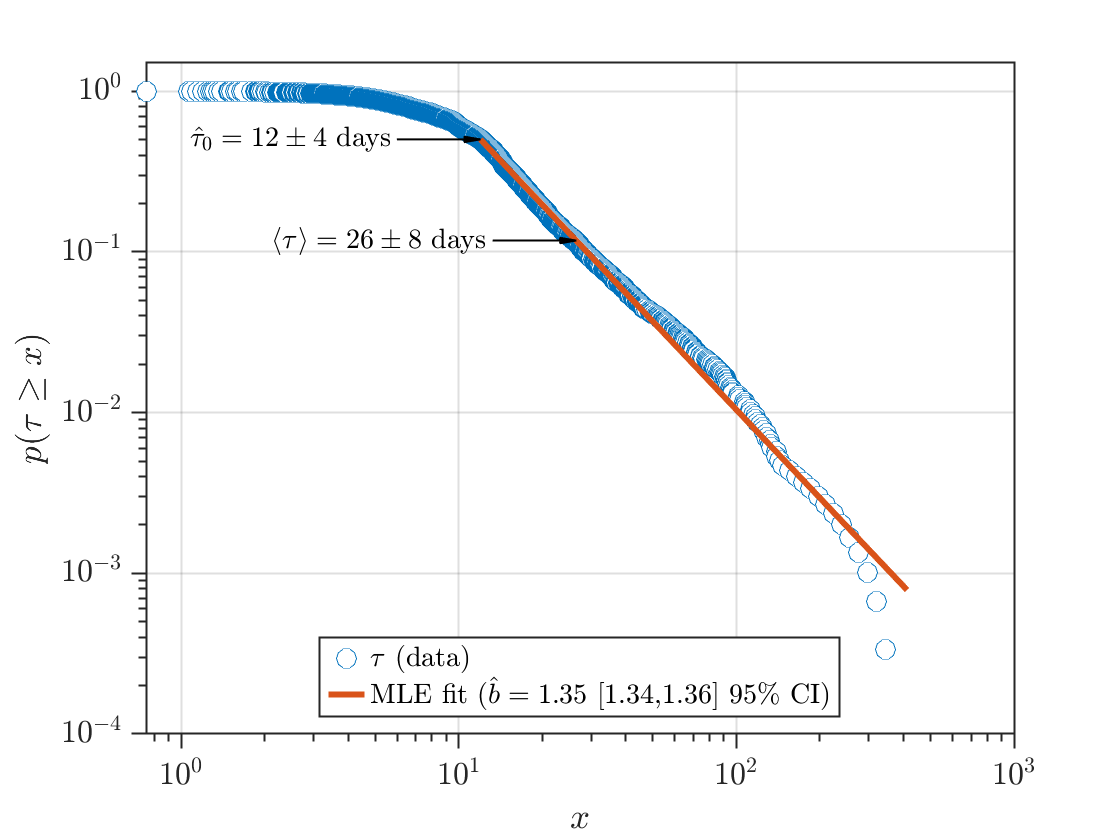

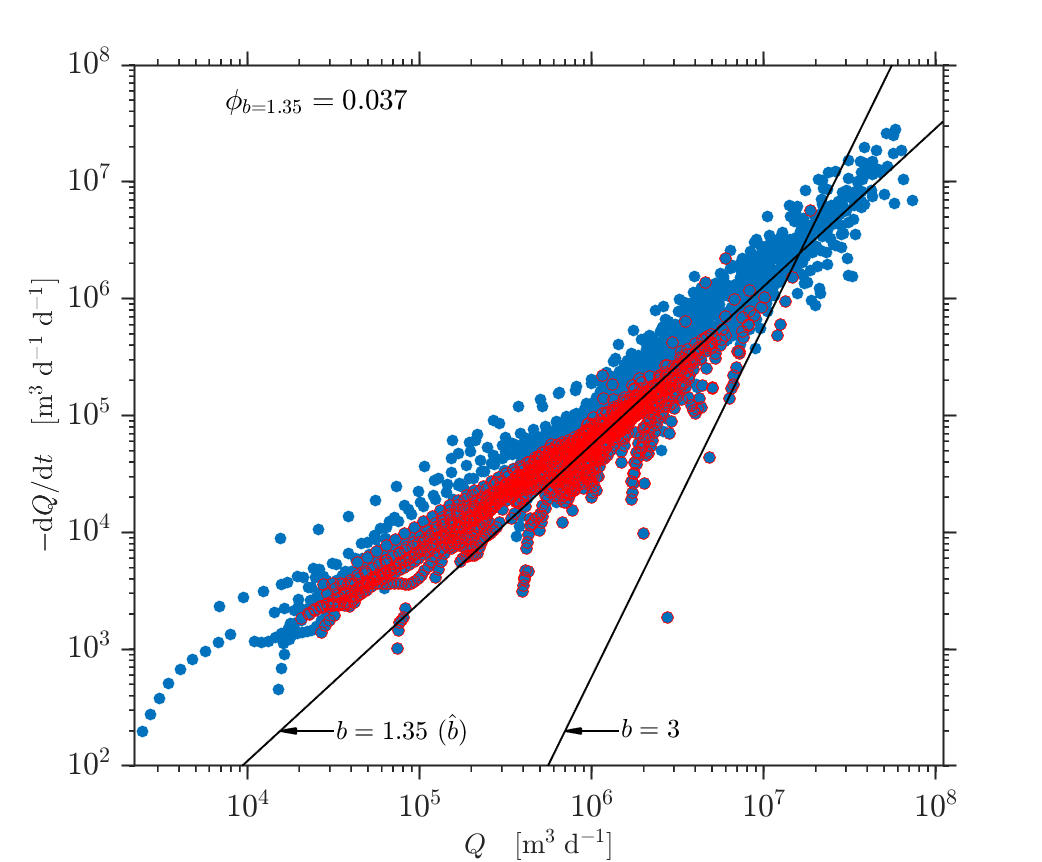

if fitglobal == true
   opts.Global = bfra.setopts('globalfit','drainagearea',A,'aquiferdepth',D, ...
      'streamlength',L,'drainagedens',Dd,'bootfit',bootfit,'nreps',nreps, ...
      'plotfits',true);
   GlobalFit = bfra.globalfit(K,Events,Fits,opts.Global);
   if savedata == true
      save(fname,'Events','Fits','K','GlobalFit','opts');
   end
else % load pre-saved data
   load(fname,'Events','Fits','K','GlobalFit','opts');
end

Take out parameters and data needed for the next steps

bhat     = GlobalFit.b;
tauexp   = GlobalFit.tau;
phihat   = GlobalFit.phi;
pQexp    = GlobalFit.pQexp;
T        = Events.T;
Q        = Events.Q;

Compute baseflow and aquifer thickness trends

[Qb,~,Qa,~,hb] = bfra.baseflowtrend(T,Q,A,'pctl',pQexp,'showfig',false); % cm/d/y
[Db,Sb]  = bfra.aquiferthickness(bhat,tauexp,phihat,Qb,true); % cm/yr
Qb       = Qb.*365.25;  % convert from cm/d/yr to cm/yr/yr

Compute the combined uncertainty

sig_dndt = bfra.dndtuncertainty(T,Qb,K,Fits,GlobalFit,opts.Global,0.05);

Add the baseflow recession analysis timeseries to the annual Data table, 

Data = addvars(Data,Qb,Sb,Db);
Data.sigDb = Data.Db.*sig_dndt;

Make separate tables for the Grace period and Calm period

inanC    = isnan(Data.Dc);%  | isnan(Data.Q);
DataC    = Data(~inanC,:);
DataG    = DataC(find(year(DataC.Time)==2002):end,:);

Plot the alt trend

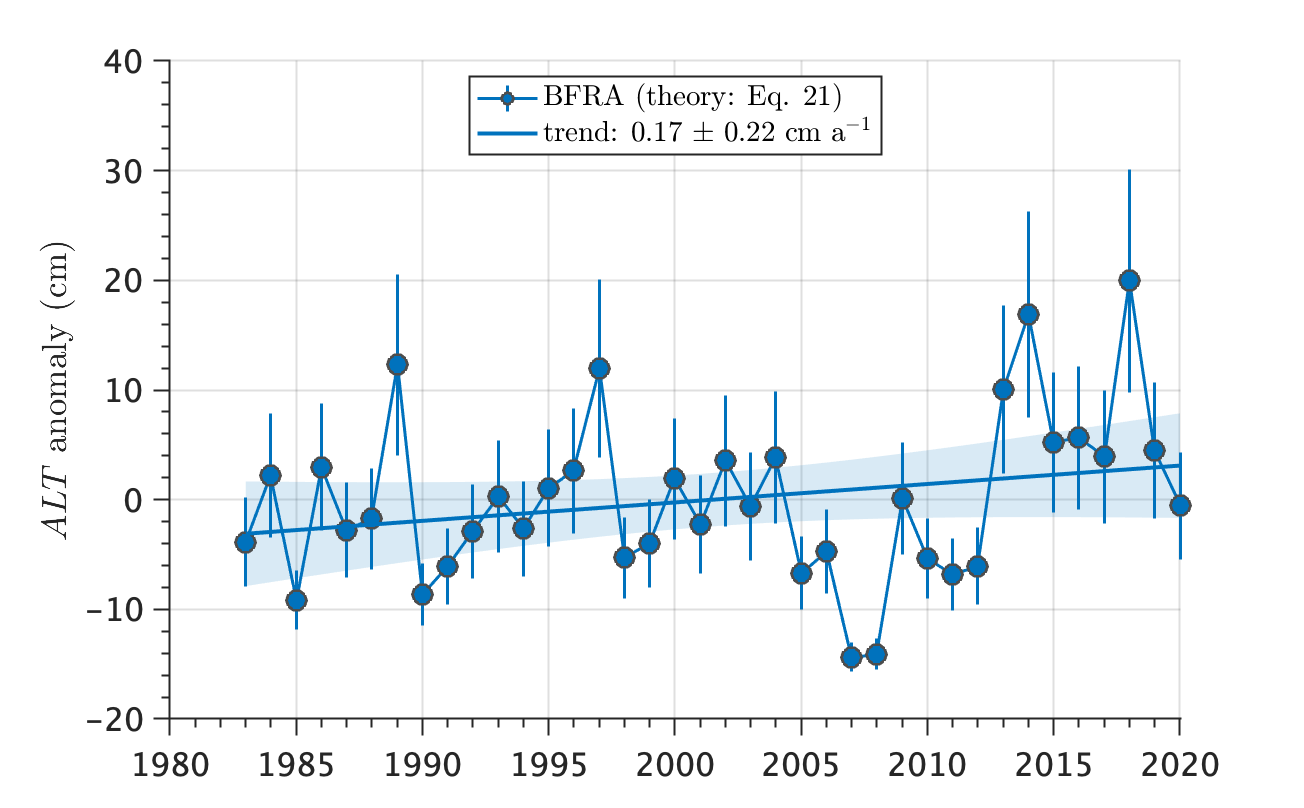

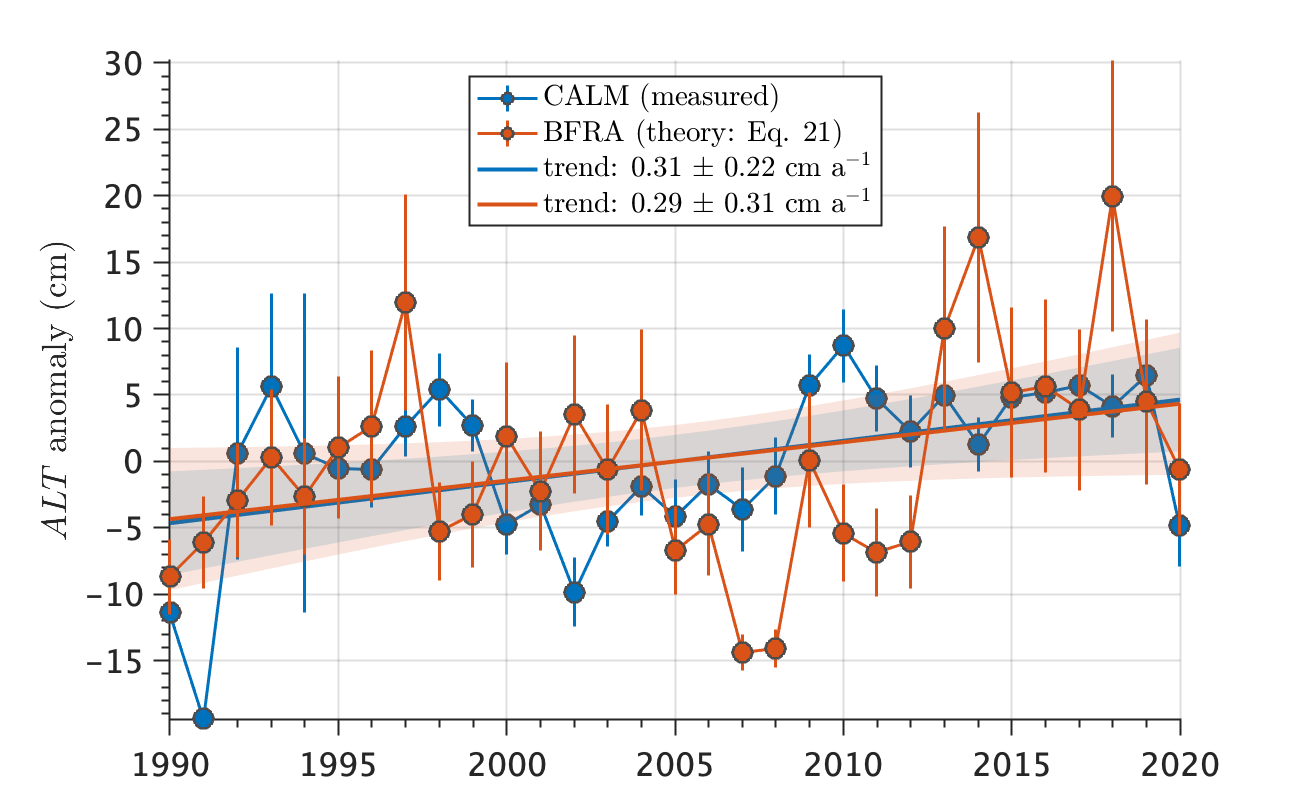

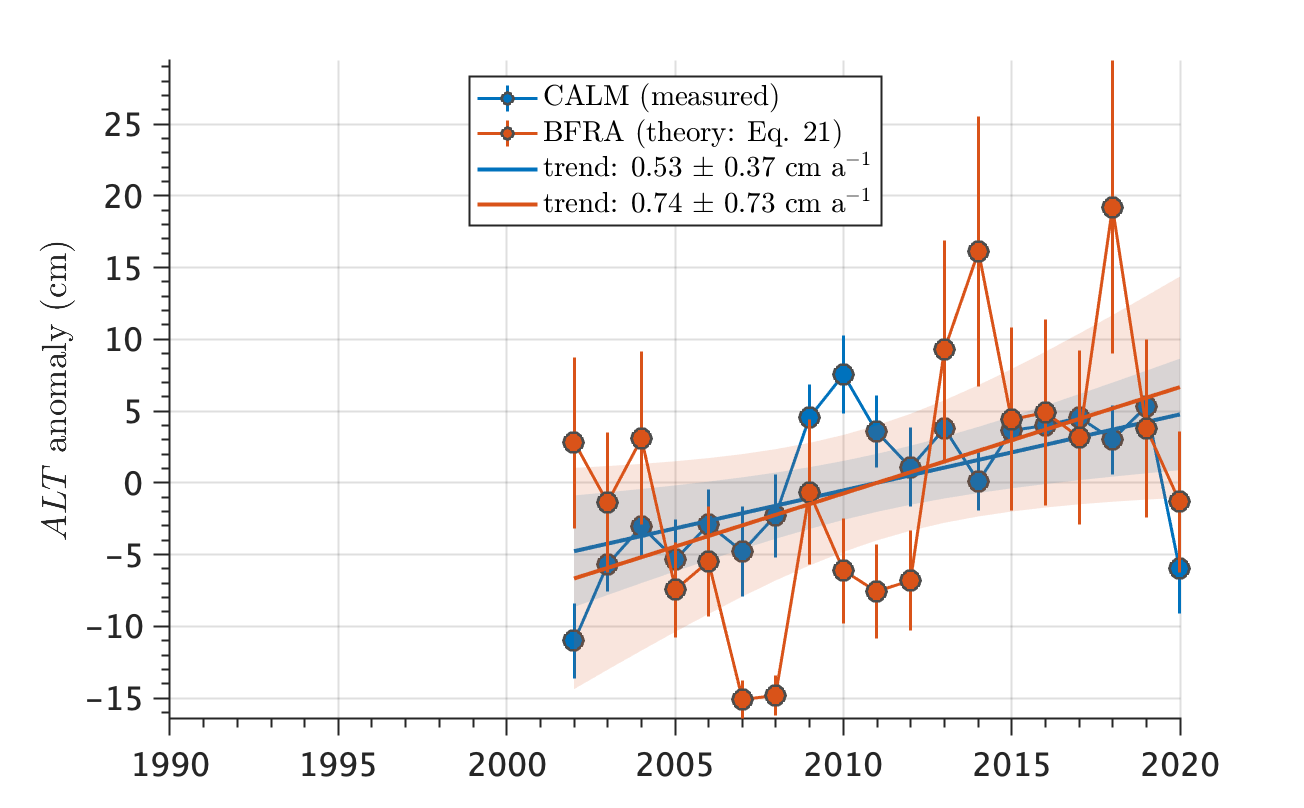

if plotfigs == true
   bfra.plotalttrend(Data.Time,Data.Db,Data.sigDb);
   bfra.plotalttrend(DataC.Time,DataC.Db,DataC.sigDb,DataC.Dc,DataC.sigDc);
   bfra.plotalttrend(DataG.Time,DataG.Db,DataG.sigDb,DataG.Dc,DataG.sigDc);
end

Save the data

if savedata == true
   save(fname,'Events','Fits','K','GlobalFit','Data','DataC','DataG','opts');
end